# ODE Symbolic

We solve the equation for harmonic oscillator:


$$% MathType!MTEF!2!1!+-
% feaagKart1ev2aaatCvAUfeBSjuyZL2yd9gzLbvyNv2CaerbuLwBLn
% hiov2DGi1BTfMBaeXatLxBI9gBamXvP5wqSX2qVrwzqf2zLnharyqw
% 1bYrVrhAPngivLeitvwBPXwANHgDaebbnrfifHhDYfgasaacH8srps
% 0lbbf9q8WrFfeuY-Hhbbf9v8qqaqFr0xc9pk0xbba9q8WqFfea0-yr
% 0RYxir-Jbba9q8aq0-yq-He9q8qqQ8frFve9Fve9Ff0dmeaabaqaci
% GacaGaaeqabaWaceaaeaaakeaaceWG4bGbamaacqGHRaWkcaaIYaGa
% aGynaiaadIhacqGH9aqpcaaIWaaaaa!458C!
\[\ddot x + 25x = 0\]$$


We can use the dsolve function:

clear; clc; close all; % Clear workspace, command window, and close figures
syms x(t)
a = 25

a = 25

Dx = diff(x);
D2x = diff(x,2);
xt = dsolve(D2x + a*x == 0, x(0) == 0, Dx(0) == 1)

$$xt = \frac{\sin\left(5\,t\right)}{5}$$

# We plot the solution using fplot:

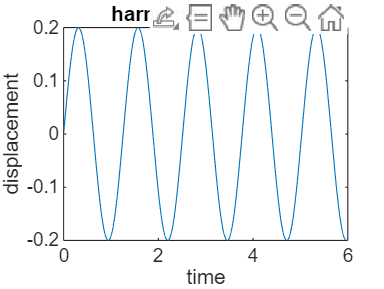

tspan = [0 6];
fplot(xt,tspan),xlabel('time'),ylabel('displacement'),
title('harmonic oscillator');

# Damped harmonic oscillator


$$% MathType!MTEF!2!1!+-
% feaagKart1ev2aaatCvAUfeBSjuyZL2yd9gzLbvyNv2CaerbuLwBLn
% hiov2DGi1BTfMBaeXatLxBI9gBamXvP5wqSX2qVrwzqf2zLnharyqw
% 1bYrVrhAPngivLeitvwBPXwANHgDaebbnrfifHhDYfgasaacH8srps
% 0lbbf9q8WrFfeuY-Hhbbf9v8qqaqFr0xc9pk0xbba9q8WqFfea0-yr
% 0RYxir-Jbba9q8aq0-yq-He9q8qqQ8frFve9Fve9Ff0dmeaabaqaci
% GacaGaaeqabaWaceaaeaaakeaaceWG4bGbamaacqGHRaWkcaaI1aGa
% bmiEayaacaGaey4kaSIaaGOmaiaaiwdacaWG4bGaeyypa0JaaGimaa
% aa!4833!
\[\ddot x + 5\dot x + 25x = 0\]$$


xtd = dsolve(D2x+5*Dx+25*x == 0,x(0) == 0, Dx(0) == 1)

$$xtd = \frac{2\,\sqrt{3}\,{\mathrm{e}}^{-\frac{5\,t}{2}}\,\sin\left(\frac{5\,\sqrt{3}\,t}{2}\right)}{15}$$

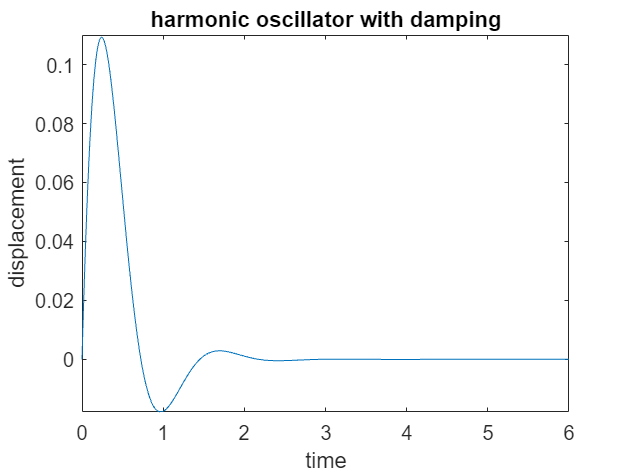

fplot(xtd,tspan),xlabel('time'),ylabel('displacement'),
title('harmonic oscillator with damping')

# Driven harmonic oscillators


$$% MathType!MTEF!2!1!+-
% feaagKart1ev2aaatCvAUfeBSjuyZL2yd9gzLbvyNv2CaerbuLwBLn
% hiov2DGi1BTfMBaeXatLxBI9gBamXvP5wqSX2qVrwzqf2zLnharyqw
% 1bYrVrhAPngivLeitvwBPXwANHgDaebbnrfifHhDYfgasaacH8srps
% 0lbbf9q8WrFfeuY-Hhbbf9v8qqaqFr0xc9pk0xbba9q8WqFfea0-yr
% 0RYxir-Jbba9q8aq0-yq-He9q8qqQ8frFve9Fve9Ff0dmeaabaqaci
% GacaGaaeqabaWaceaaeaaakeaaceWG4bGbamaacqGHRaWkcaaI1aGa
% bmiEayaacaGaey4kaSIaaGOmaiaaiwdacaWG4bGaeyypa0JaaGymai
% aaicdacqGHflY1ciGGZbGaaiyAaiaac6gacaGGOaGaamiDaiaacMca
% aaa!5062!
\[\ddot x + 5\dot x + 25x = 10 \cdot \sin (t)\]$$


xtdr = dsolve(D2x+5*Dx+25*x == 10*sin(t),x(0)==0,Dx(0)==0)

$$xtdr = \begin{array}{l} \frac{50\,\sigma_{2}\,\cos\left(\sigma_{1}\right)}{601}-\cos\left(\sigma_{1}\right)\,\left(\frac{25\,\cos\left(t-\sigma_{1}\right)}{601}+\frac{25\,\cos\left(t+\sigma_{1}\right)}{601}-\frac{120\,\sin\left(t-\sigma_{1}\right)}{601}-\frac{120\,\sin\left(t+\sigma_{1}\right)}{601}+\frac{130\,\sqrt{3}\,\cos\left(t-\sigma_{1}\right)}{1803}-\frac{130\,\sqrt{3}\,\cos\left(t+\sigma_{1}\right)}{1803}-\frac{23\,\sqrt{3}\,\sin\left(t-\sigma_{1}\right)}{1803}+\frac{23\,\sqrt{3}\,\sin\left(t+\sigma_{1}\right)}{1803}\right)-\frac{2\,\sqrt{3}\,\sin\left(\sigma_{1}\right)\,\left(\frac{\frac{5\,\sin\left(t\,\left(\sigma_{3}-1\right)\right)}{2}-\cos\left(t\,\left(\sigma_{3}-1\right)\right)\,\left(\sigma_{3}-1\right)}{{\left(\sigma_{3}-1\right)}^{2}+\frac{25}{4}}-\frac{\frac{5\,\sin\left(t\,\left(\sigma_{3}+1\right)\right)}{2}-\cos\left(t\,\left(\sigma_{3}+1\right)\right)\,\left(\sigma_{3}+1\right)}{{\left(\sigma_{3}+1\right)}^{2}+\frac{25}{4}}\right)}{3}+\frac{46\,\sqrt{3}\,\sigma_{2}\,\sin\left(\sigma_{1}\right)}{3\,\left(5\,\sqrt{3}-26\right)\,\left(5\,\sqrt{3}+26\right)}\\ \mathrm{where}\\ \sigma_{1}=\frac{5\,\sqrt{3}\,t}{2}\\ \sigma_{2}={\mathrm{e}}^{-\frac{5\,t}{2}}\\ \sigma_{3}=\frac{5\,\sqrt{3}}{2} \end{array}$$

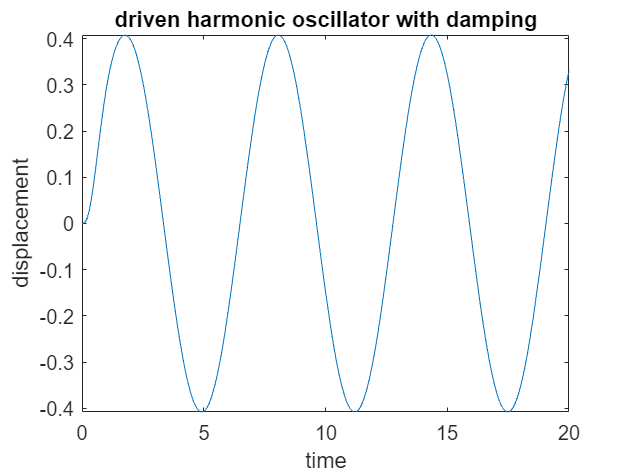

tspan2 = [0 20];
fplot(xtdr,tspan2),xlabel('time'),ylabel('displacement'),
title('driven harmonic oscillator with damping');